# Gedämpfte Schwingung (Live Script Demo)

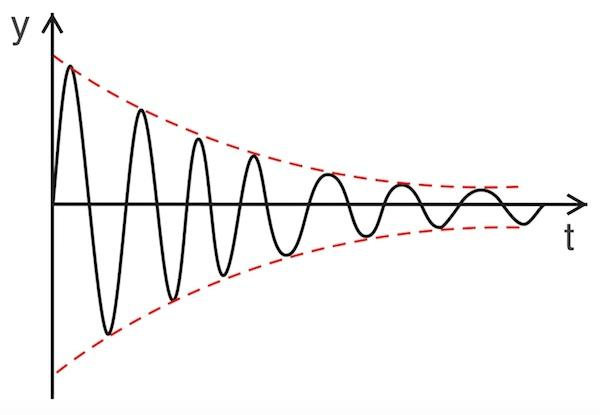

Exercise description: Consider the following equations:


$$\begin{array}{l}
\textrm{y1}=\sin \left(\omega \;x\right)\\
\textrm{y2}=\exp \left(-k\;x\right)
\end{array}$$


Omega is the frequency of the oscillation and k is the damping coefficient.

omega =7;
k =1.6;

The resulting damped oscillation is given by the product y1*y2. Calculate the three curves and plot them on the interval x=[0,2pi] using 100 samples using different line styles and markers.

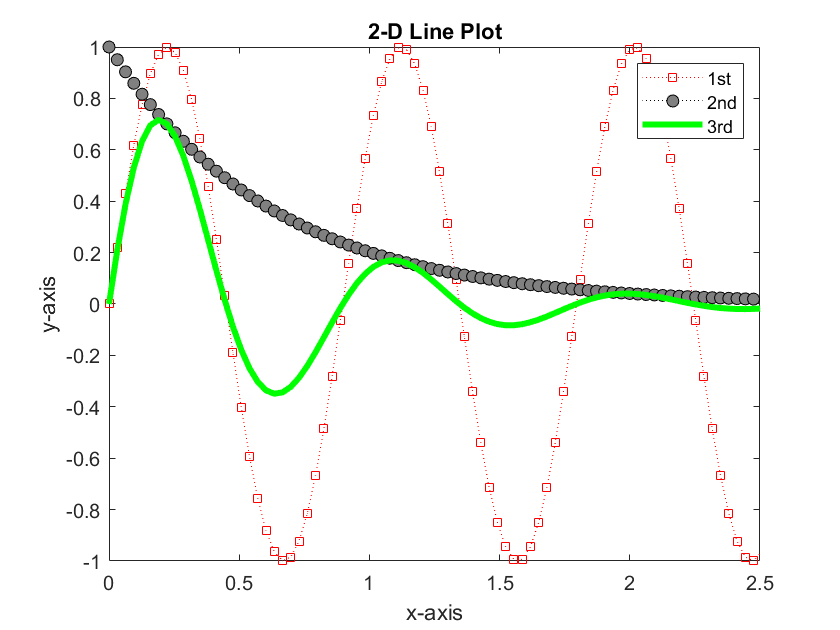

x = linspace(0,pi,100);
y1 = sin(omega*x);
y2 = exp(-k*x);

plot(x,y1,':rs')
hold on
plot(x,y2,':ko','MarkerFaceColor',[0.5,0.5,0.5])
% calculate the product of the two functions
prod=y1.*y2;

% Create a line plot and use the LineSpec option to specify a dashed green line with square markers.
% Use Name,Value pairs to specify the line width, marker size, and marker colors. Set the marker edge color to blue and set the marker face color using an RGB color value.
plot(x,prod,'-g','LineWidth',3)

%mark the point x(40),y1(40) with a black o marker and the following properties 'LineWidth',3, 'MarkerSize',15,'MarkerEdgeColor','k'

hold off %disable the hold

title('2-D Line Plot')
xlabel('x-axis')
ylabel('y-axis')
legend('1st','2nd','3rd')

%set the x-axis limits to [0:2.5]
xlim([0 2.5])